# 正体不明な系の入出力関係をボード線図にしてみる

DCモータパラメータの読み込み

clear;
R = 0.1;    % 巻線抵抗(Ω)
L = 6e-3;   % インダクタンス(H)
Kt = 0.1;   % トルク定数(Nm/A)
D = 0.001;  % 減衰係数(Nm/(rad/s))
J = 4e-4;   % イナーシャ(kg*m^2)

シミュレーションを実行、結果をワークスペースに保存(Switchブロックの接続先をチャープ信号入力ブロックに設定しておく必要あり)

mdlName = 'Fig3_dcMotorModel';
open(mdlName);
out = sim(mdlName);

シミュレーション結果を用いたボード線図(ゲイン、位相)の推定

x = out.simVoltage.Data;
y = out.simOmega.Data;
x = reshape(x, [], 1);
y = reshape(y, [], 1);

Ts = out.simVoltage.Time(2)-out.simVoltage.Time(1);
Fs = 1/Ts;

% 推定するボード線図の周波数上下限を規定
F = logspace(-1,3,100); 

% ボード線図の推定
[txy,Freq_fromData] = tfestimate(x,y,[],[],F,Fs);

w_fromData = F * 2 * pi;
Gain_fromData = 20*log10(abs(txy));
Phase_fromData = angle(txy) * 180 / pi;

推定したボード線図の描画(図8に対応)

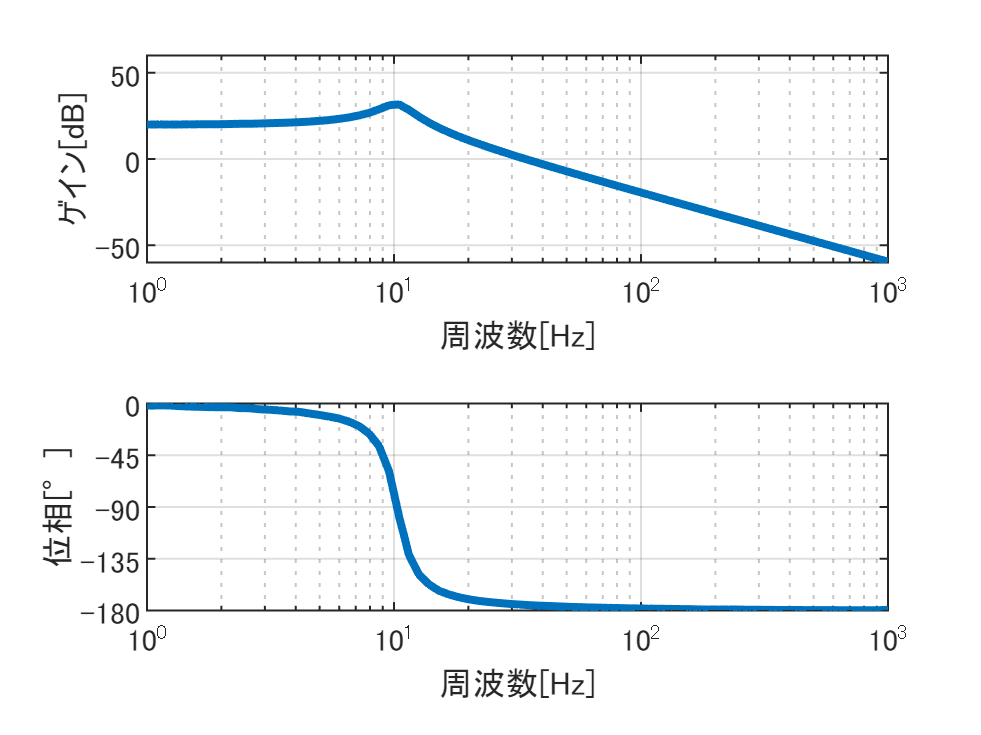

figure;
tiledlayout('flow')
sp1 = nexttile(1);
sp1.FontSize = 11;
slg = semilogx(Freq_fromData, Gain_fromData);
slg.LineWidth = 2;

hold on; grid on;
axis([1, 1000, -60, 60]);
xlabel("周波数[Hz]");
ylabel("ゲイン[dB]");

sp2 = nexttile(2);
sp2.FontSize = 11;
slp = semilogx(Freq_fromData, Phase_fromData);
slp.LineWidth = 2;
hold on; grid on;
axis([1, 1000, -180, 0]);
yticks(-180: 45: 0);
xlabel("周波数[Hz]");
ylabel("位相[°]");

## ボード線図を用いた伝達関数の類推

### 伝達関数パラメータの推定

上記に示したボード線図における低周波ゲイン値、およびゲイン線図頂点における周波数値より類推した伝達関数に含まれるパラメータを推定。ボード線図の描画までを行う。(図10に対応)

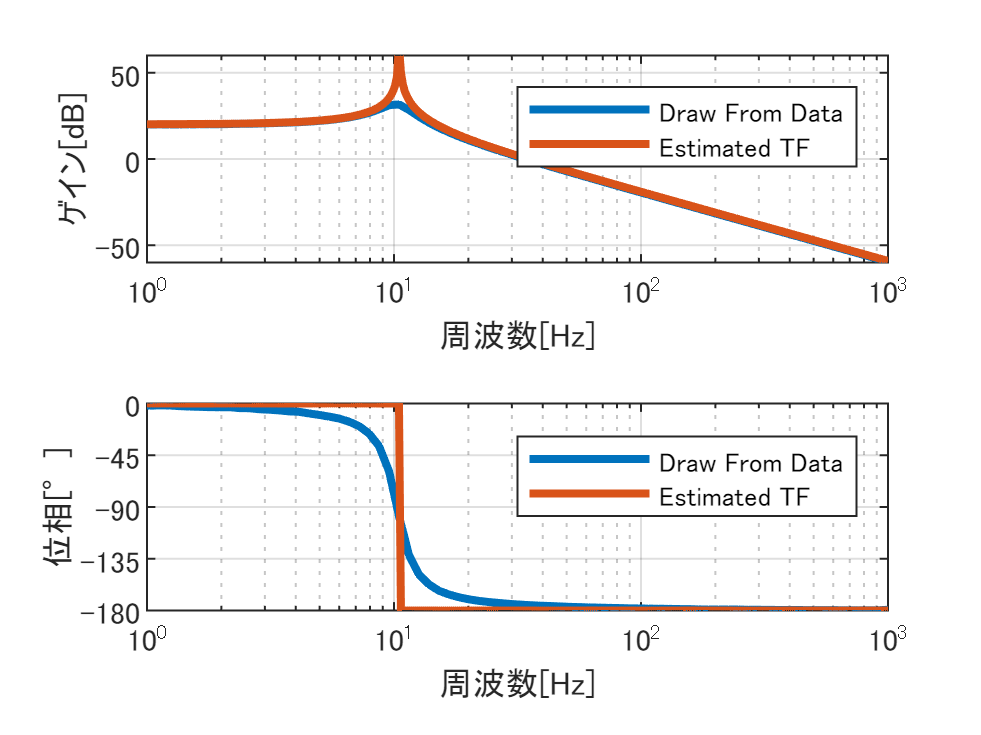

s = tf('s');

% 推定したパラメータK, ωnを含む伝達関数の定義
K = 10.1;
omega_n = 10.5*2*pi;
Ps = K * omega_n^2/(s^2+omega_n^2);

% 伝達関数からボード線図を作成
Freq = logspace(-1, 3, 500).';
w = 2 * pi * Freq;

[Mag, Phase] = bode(Ps, w);                 % ゲイン、位相の算出
Gain = 20 * log10( reshape(Mag, [], 1) );   % ゲインデータ成形および単位変換
Phase = reshape(Phase, [], 1);              % 位相データの成形

nexttile(1);
slg = semilogx(Freq, Gain);
slg.LineWidth = 2;
legend('Draw From Data','Estimated TF')

nexttile(2);
slp = semilogx(Freq, Phase);
slp.LineWidth = 2;
legend('Draw From Data','Estimated TF')

## 減衰係数をボード線図から推定し伝達関数を作る

2次遅れ系伝達関数パラメータのうち、減衰係数ζをボード線図読み取り結果より推定。ボード線図の描画までを行う。(図13に対応)

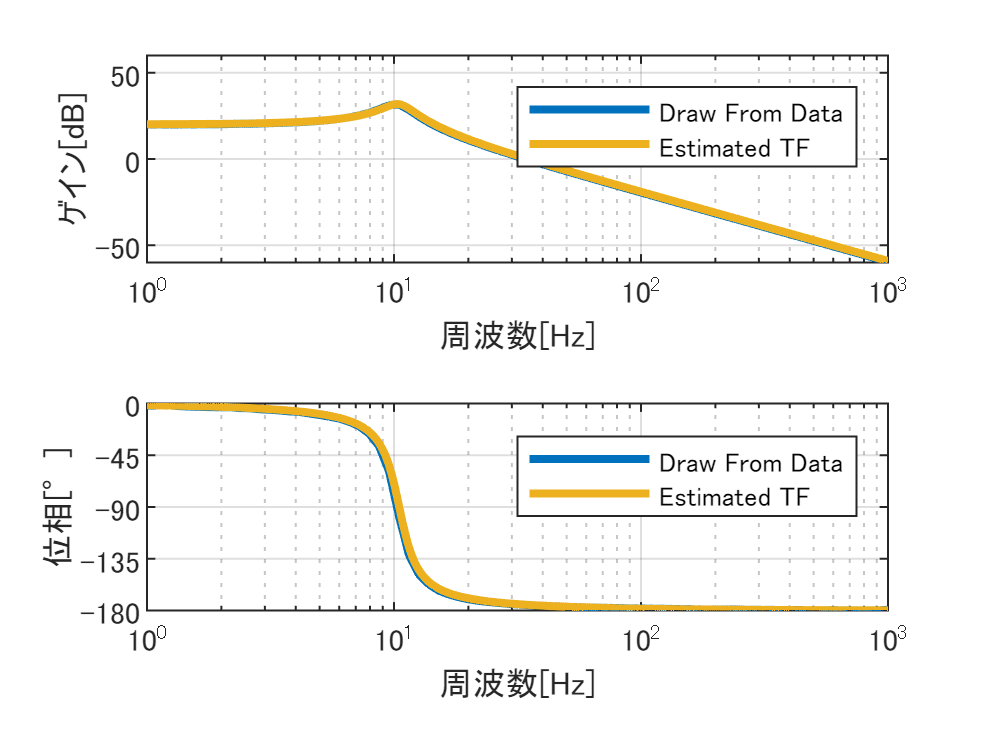

% 推定したパラメータK, ωn, ζを含む伝達関数の定義
K = 10.1;
omega_n = 10.5*2*pi;
zeta = 0.13;
Ps = K * omega_n^2/(s^2 + 2 * zeta * omega_n * s + omega_n^2);

% 伝達関数からボード線図を作成
Freq = logspace(-1, 3, 500).';
w = 2 * pi * Freq;

[Mag, Phase] = bode(Ps, w);                 % ゲイン、位相の算出
Gain = 20 * log10( reshape(Mag, [], 1) );   % ゲインデータ成形および単位変換
Phase = reshape(Phase, [], 1);              % 位相データの成形

nexttile(1);
delete(slg); % 減衰係数を考慮しない場合のゲイン線図を削除
slg = semilogx(Freq, Gain);
slg.LineWidth = 2;
legend('Draw From Data','Estimated TF')

nexttile(2);
delete(slp); % 減衰係数を考慮しない場合の位相線図を削除
slp = semilogx(Freq, Phase);
slp.LineWidth = 2;
legend('Draw From Data','Estimated TF')

### MATLABを用いた推定パラメータの検算

invfreqs関数を用いることでtfestimate関数にて推定されたボード線図(周波数応答データ)をもとに伝達関数の推定を行う。

[Be,Ae]=invfreqs(txy, w_fromData, 0, 2);

Ps_e = tf(Be, Ae)

Ps_e =
 
        4.156e04
  --------------------
  s^2 + 16.46 s + 4193
 
連続時間の伝達関数です。



tfestimate関数にて推定されたボード線図と、invfreqs関数によって推定された伝達関数とを重ねてみる(図13に対応)

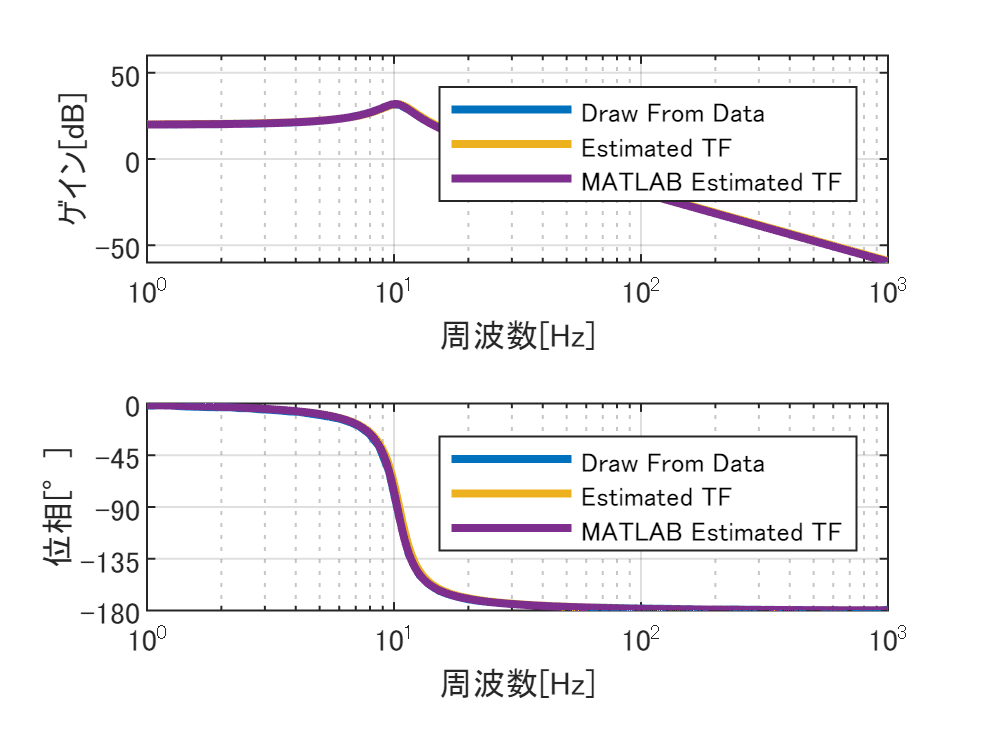

[Mag, Phase] = bode(Ps_e, w);                 % ゲイン、位相の算出
Gain_e = 20 * log10( reshape(Mag, [], 1) );   % ゲインデータ成形および単位変換
Phase_e = reshape(Phase, [], 1);              % 位相データの成形

nexttile(1);
slg = semilogx(Freq, Gain_e);
slg.LineWidth = 2;
legend('Draw From Data','Estimated TF','MATLAB Estimated TF')

nexttile(2);
slp = semilogx(Freq, Phase_e);
slp.LineWidth = 2;
legend('Draw From Data','Estimated TF','MATLAB Estimated TF')

## 2次遅れ系を対象としたPID制御設計

1次遅れ系を規範モデルとしたモデルマッチング法にてPIDゲインを設計、シミュレーションにて効果確認を行う。

% 2次遅れ系のパラメータ
K = 10.1;                   % ゲイン
omega_n = 10.5*2*pi;        % 共振角周波数(rad/s)
zeta = 0.13;                % 減衰係数

% 規範モデルのパラメータ
tauc = 0.05;                % 時定数(s)

% 不完全微分のパラメータ
taud = 0.0001;              % 不完全微分の時定数(s)

% PID制御器ゲイン
Kp = 2*zeta/(K*omega_n*tauc);   % P制御ゲイン
Ki = 1/(K*tauc);                % I制御ゲイン
Kd = 1/(K*omega_n^2*tauc);      % D制御ゲイン


シミュレーションの実行および結果のプロット(図19に対応)

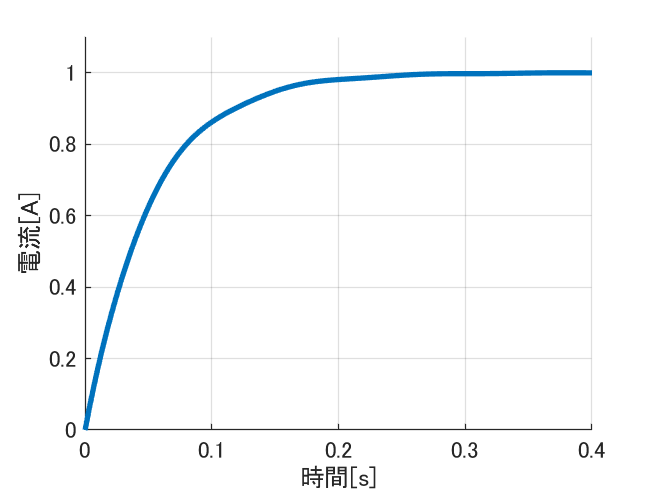

figure();
hold on; grid on;

mdlName = 'Fig15_dcMotorModel_PIDcontrol';
open(mdlName);
out = sim(mdlName);

plot(out.simOmega, 'LineWidth',2); 

axis([0, 0.4, 0, 1.1]);
xlabel("時間[s]");
ylabel("電流[A]");

## コラム PID・1次遅れ系規範モデルの「闇」

規範モデルの時定数を0.05より小さく設定した場合、振動が発生する。(図Aに対応)

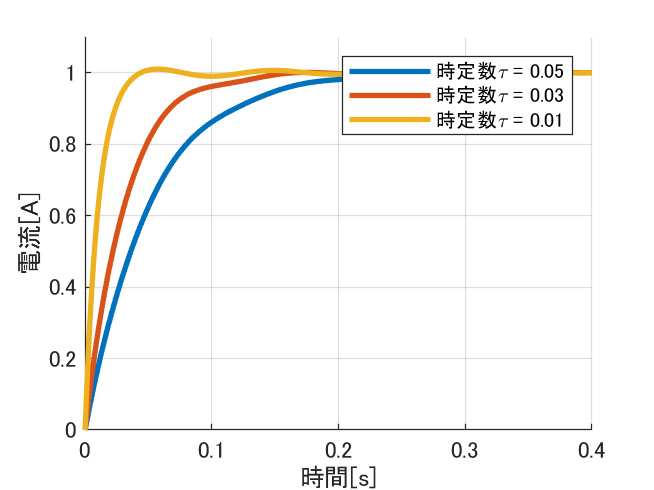

% 規範モデルのパラメータ
tauc = [0.05 0.03 0.01];   % 時定数(s)

figure();
hold on; grid on;
legendTxt = "時定数\tau = " + string(tauc.');

% 2次遅れ系のパラメータ
K = 10.1;                   % ゲイン
omega_n = 10.5*2*pi;        % 共振角周波数(rad/s)
zeta = 0.13;                % 減衰係数

% 不完全微分のパラメータ
taud = 0.0001;              % 不完全微分の時定数(s)

% 規範モデルの時定数ごとにシミュレーションを実行しプロット
mdlName = 'Fig15_dcMotorModel_PIDcontrol';
for ii = 1:length(tauc)
    % PID制御器ゲイン
    Kp = 2*zeta/(K*omega_n*tauc(ii));   % P制御ゲイン
    Ki = 1/(K*tauc(ii));                % I制御ゲイン
    Kd = 1/(K*omega_n^2*tauc(ii));      % D制御ゲイン
    out = sim(mdlName);
    plot(out.simOmega, 'LineWidth',2); 
end
axis([0, 0.4, 0, 1.1]);
xlabel("時間[s]");
ylabel("電流[A]");
legend(legendTxt);

パラメータ推定精度が高い場合であっても、外部要因によりパラメータが変動してしまった場合において振動を抑えることが出来ない。(図Bに対応)

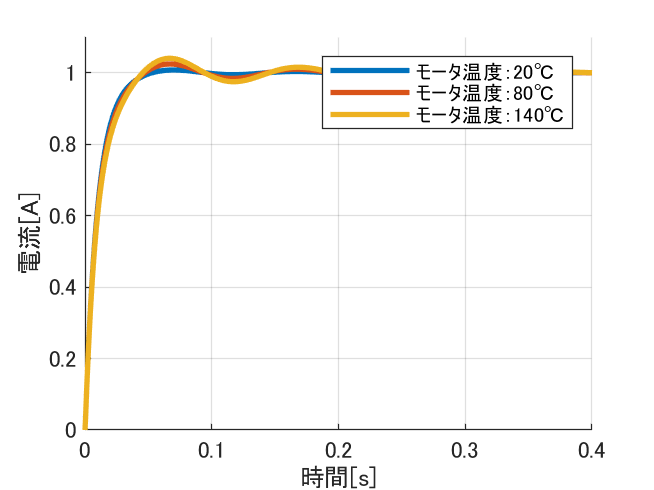

% 規範モデルのパラメータ
tauc = 0.01;   % 時定数(s)
Temp = [20 80 140]; % モータ温度(℃)

figure();
hold on; grid on;
legendTxt = "モータ温度：" + string(Temp.') + "℃";

% 2次遅れ系のパラメータ
K = 10.1;                   % ゲイン
omega_n = 10.3*2*pi;        % 共振角周波数(rad/s)
zeta = 0.13;                % 減衰係数

% PID制御器ゲイン
Kp = 2*zeta/(K*omega_n*tauc);   % P制御ゲイン
Ki = 1/(K*tauc);                % I制御ゲイン
Kd = 1/(K*omega_n^2*tauc);      % D制御ゲイン

% 不完全微分のパラメータ
taud = 0.0001;              % 不完全微分の時定数(s)

% モータ温度ごとにシミュレーションを実行しプロット
tempCoef = 0.00393;         % 抵抗の温度係数(1/℃)
mdlName = 'Fig15_dcMotorModel_PIDcontrol';
for ii = 1:length(Temp)
    % モータパラメータの温度変動模擬
    R_20 = 0.1;     % 基準温度20℃のときの抵抗(Ω)
    R = R_20 * ( 1 +  tempCoef * (Temp(ii) - 20) ); % 温度によるパラメータ変動
    out = sim(mdlName);
    plot(out.simOmega, 'LineWidth',2); 
end
axis([0, 0.4, 0, 1.1]);
xlabel("時間[s]");
ylabel("電流[A]");
legend(legendTxt);

DCモータ温度20℃前提で設計されたPID制御器の伝達関数と、DCそのものの伝達関数(20℃～140℃)を比較する。(図Cに対応)

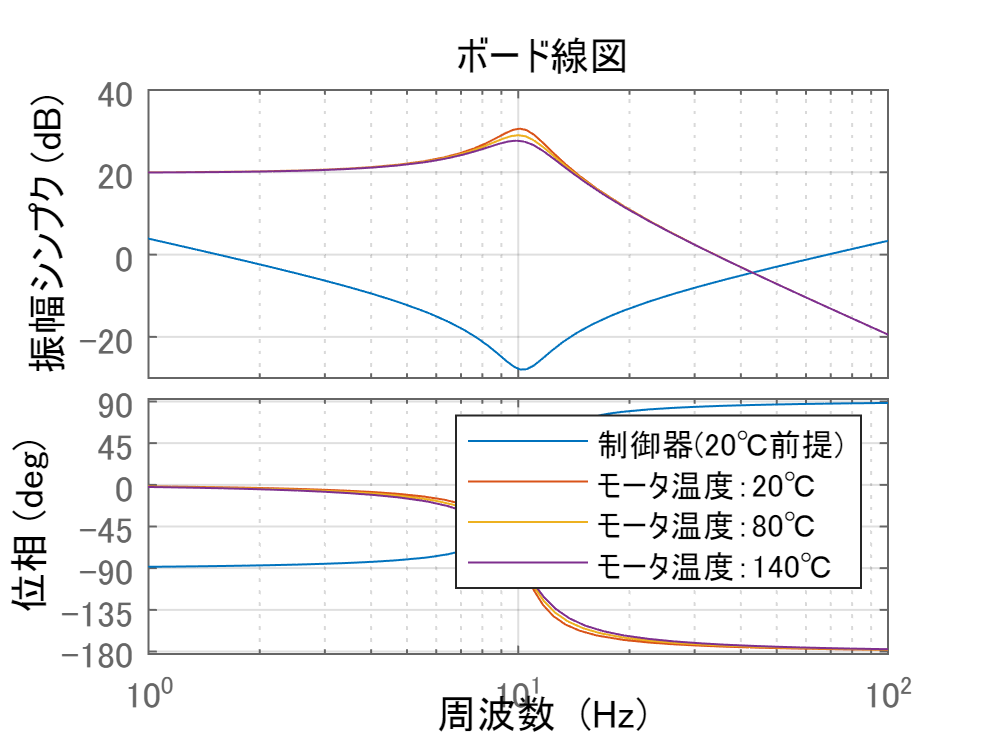

figure();
Cs = Kp + Ki/s + s*Kd; % PID制御器の伝達関数
bode(Cs);
hold on; grid on;

for ii = 1:length(Temp)
    % モータパラメータの変動模擬
    R_20 = 0.1;     % 基準温度20℃のときの抵抗(Ω)
    R = R_20 * ( 1 + tempCoef * (Temp(ii) - 20) ); % 温度によるパラメータ変動
    Ps = Kt/((J*s + D)*(L*s + R) + Kt^2); % DCモータの伝達関数
    bode(Ps);
end
legend(["制御器(20℃前提)";legendTxt]);

I-PD制御器と2次遅れ系規範モデルの適用によるロバスト性の高い制御設計(図Dに対応)

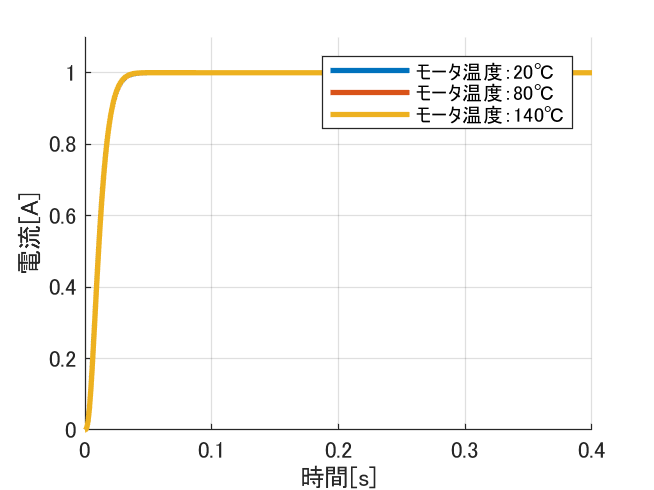

%% IPD制御　２項係数標準系
mdlName = 'FigD_dcMotorModel_IPDcontrol.slx';

alpha1 = 3;
alpha2 = 3;

wnc = 40*2*pi;
Ki = wnc^3 / (K*omega_n^2);
Kd = ( alpha2 * wnc - 2*zeta*omega_n ) / (K*omega_n^2);
Kp = ( alpha2 * wnc^2 - omega_n^2 )/ (K*omega_n^2);

figure(); hold on; grid on;
open(mdlName);

for ii = 1:length(Temp)
    % モータパラメータの変動模擬
    R_20 = 0.1;     % 基準温度20℃のときの抵抗(Ω)
    R = R_20 * ( 1 + tempCoef * (Temp(ii) - 20) ); % 温度によるパラメータ変動
    out = sim(mdlName);
    plot(out.simOmega, 'LineWidth',2); 
end

axis([0, 0.4, 0, 1.1]);
xlabel("時間[s]");
ylabel("電流[A]");
legend(legendTxt);